# A Schrodinger-Poisson problem with an unbounded edge

Set up a quantum graph in the form of a dumbbell plus one extra unbounded edge

Solve the vertex-value problem 


$$\triangle u - V(x)\, u= f \\
\sum w u'(\mathtt{v_1})+ u(\mathtt{v_1}) = 8 \\
\sum w u'(\mathtt{v_2})+ u(\mathtt{v_2}) = 3\\
\lim_{x\to\infty} u_3(x) = 0
$$


where 

- The potential is $\{ 2 \cos{2x},0,0,0,0\}$

- The functions on the right-hand-sides are $f = \left\{
-\sin{3x},
2\cos{2x},
-4,
-\sin{x},
\sech{x}-2 \sech^3{x}
\right\}$on the five edges.

- the edges have lengths $\left\{
\pi, 2\pi,1, 2\pi, \infty
\right\}$

- The weight vector is $w=(1, 1, 2, 1, 1)$.

- The exact solutions on the edges are $\left\{
\sin{x},
\sin^2{x},
3x-2x^2,
1+\sin{x},
\sech{x}
\right\}$.

The exact solution is computed in the accompanying Mathematica notebook of the same name.

## Quantum graph definition

s=[1 1 1 2 2];
t=[1 1 2 2 3];
L=[pi 2*pi 1 2*pi inf];
robinCoeff=[1 1 nan];
weight = [1 1 2 1 1];

## The exact solution

u1=@(x)sin(x);
u2=@(x)sin(x).^2;
u3=@(x)(3*x-2*x.^2);
u4=@(x)(1+sin(x));
u5=@(x)sech(x);

## The right hand sides

Edges and nodes

f1=@(x)-sin(3*x);
f2=@(x)2*cos(2*x);
f3=-4;
f4=@(x)-sin(x);
f5=@(x)sech(x).*(1-2*sech(x).^2);
nodeData = [8;3;0];

## Solve the system twice,

doubling the number of discretization points between the two runs.

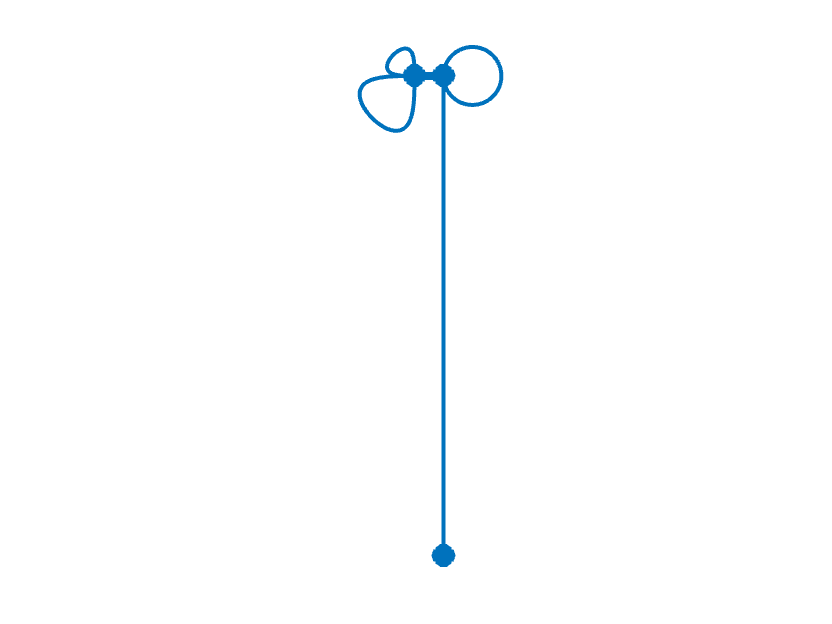

nx = 32*[1 2];
errors=zeros(1,2);
for k=1:2

Define the quantum graph (all that changes between the two iterates is the number of discretization points per unit length).

    Phi=quantumGraph(s,t,L,'RobinCoeff',robinCoeff,'nxVec',nx(k),'Weight',weight);
    Phi.addPlotCoords(@poissonExamplePlotCoords);
    Phi.addPotential({@(x)(2*cos(2*x)),0,0,0,0});
    Phi.plot('mutelayout')

Set up the exact solution on the edges

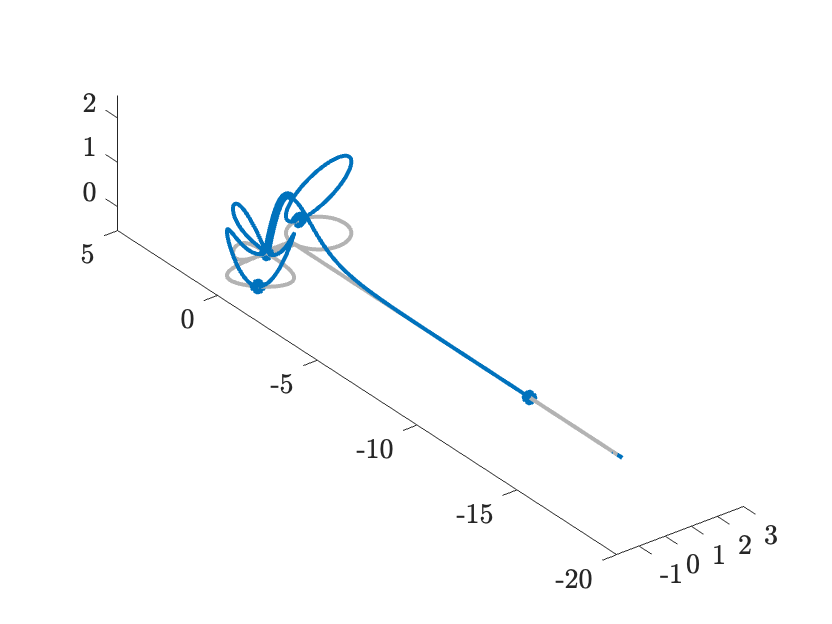

    exactSolution = Phi.applyFunctionsToAllEdges({u1,u2,u3,u4,u5});

Set up the nonhomogeneous data on the edges

    edgeData = Phi.applyFunctionsToAllEdges({f1,f2,f3,f4,f5});

The error with N=32 is 3.9262e-04.


Solve and compute errors

    numericalSolution = Phi.solvePoisson('edgeData',edgeData,'nodeData',nodeData);

The error with N=64 is 9.7957e-05.


    errors(k)= Phi.norm(exactSolution-numericalSolution,inf);

The maximum error went down by a factor of 4.0080.


end

Plot the solution

Phi.plot(numericalSolution)

Display the reduction in error. Since the discretization is second order, this should be about a factor of four.

fprintf('The error with N=%i is %0.4d.\n',nx(1),errors(1))
fprintf('The error with N=%i is %0.4d.\n',nx(2),errors(2))
fprintf("The maximum error went down by a factor of %0.4f.\n", errors(1)/errors(2) )